# DSZOB, cvičenie 7.

## **Zadanie:**

## **Úloha 1 - Formantová analýza**

Načítajte si nahrávku z dokumentového servera (vowels.m4a).

Vykonajte analýzu jednotlivých samohlások pomocou spektrogramu v danej nahrávke. Identifikujte hodnoty jednotlivých formantov. Na základe tabuľky sa pokúste identifikovať o aké anglické samohlásky ide. Overte si výpočet vypočutím nahrávky.

Ako pomôcku môžete použiť nasledujúcu tabuľku:

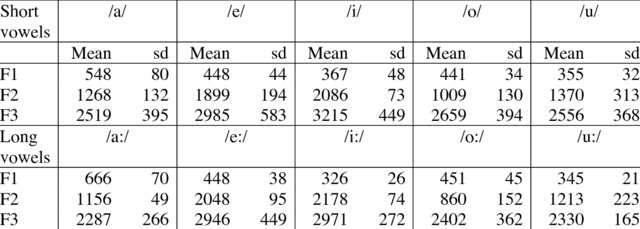

**Solution:**

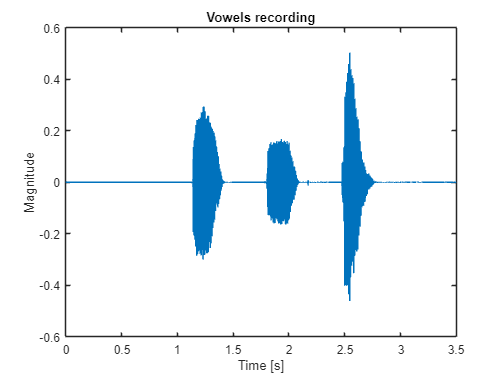

% Riešenie / Solution
clear;
vowel = audioread("Asignments\Assignment_6\vowels.m4a");
vowel_info = audioinfo("Asignments\Assignment_6\vowels.m4a");

fs = vowel_info.SampleRate;
time_axis = 0:1/fs:vowel_info.Duration;

plot(time_axis, vowel);
title("Vowels recording");
xlabel("Time [s]");
ylabel("Magnitude");

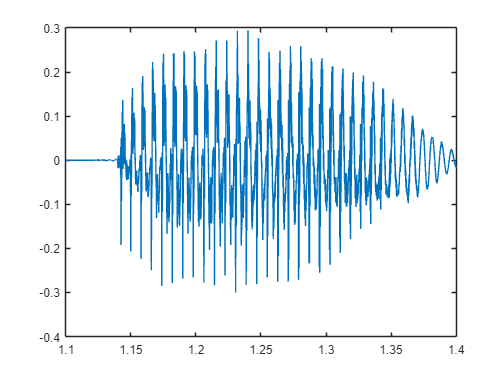

% Finding time range of first vowel
plot(time_axis, vowel);
xlim([1.1, 1.4])

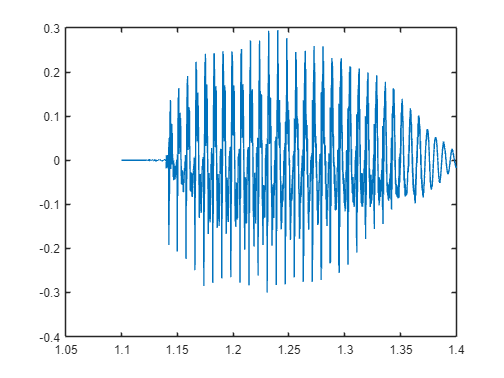

%sample for one vowel
start = round(fs*1.1);
finish = round(fs*1.4);

vowel_sample = vowel(start:finish,:);
time_axis_sample = time_axis(:,start:finish).';
plot(time_axis_sample, vowel_sample)

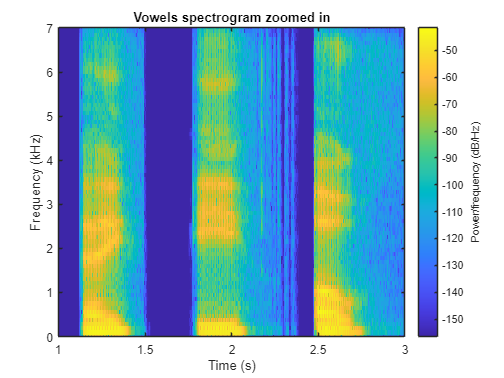

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([0, 7]);
xlim([1,3]);
title("Vowels spectrogram zoomed in");

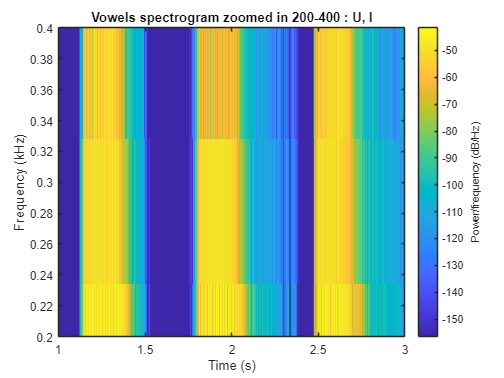

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([.2,.4]);
xlim([1,3]);
title("Vowels spectrogram zoomed in 200-400 : U, I");

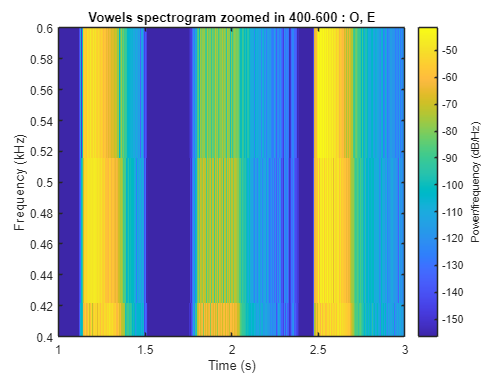

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([.4,.6]);
xlim([1,3]);
title("Vowels spectrogram zoomed in 400-600 : O, E");

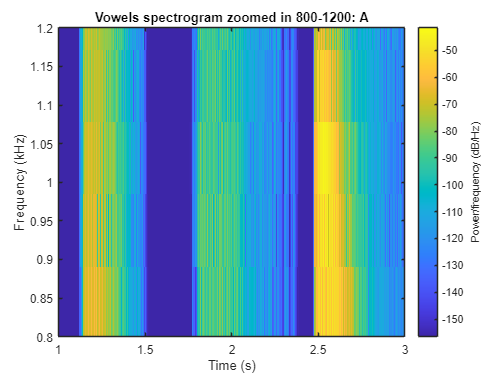

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([.8,1.2]);
xlim([1,3]);
title("Vowels spectrogram zoomed in 800-1200: A");

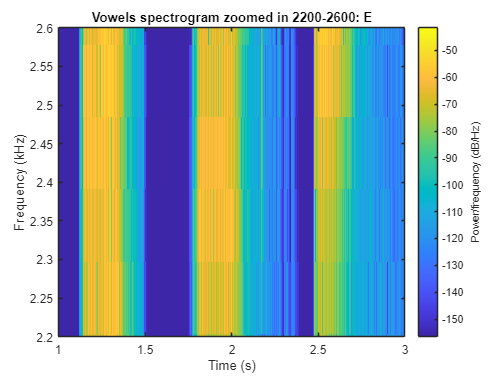

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([2.2,2.6]);
xlim([1,3]);
title("Vowels spectrogram zoomed in 2200-2600: E");

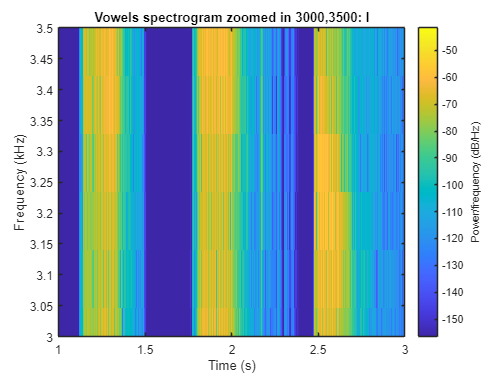

spectrogram(vowel, hamming(512), 256, 512, fs, 'yaxis');
ylim([3,3.5]);
xlim([1,3]);
title("Vowels spectrogram zoomed in 3000,3500: I");

% first o, middle u, last a (my guess)
%playblocking(audioplayer(vowel, fs));
% ok it was a, i, o

## Zadanie 2 - Fundamentálna frekvencia

Pre jednu z hlások z nahrávky vykonajte odhad fundamentálnej frekvencie pomocou complexného cepstra.

- Vezmite okienko 2048 hodnôt zo stredu zvolenej samohlásky

- Pre toto vybrané okno vypočítajte complexné cepstrum (cceps)

- Vizualizujte peak vo výsledku v rozsahu približne 0.002 - 0.01s

- Vypočítte príslušnú frekvenciu nájdeného peaku (f = 1/T)

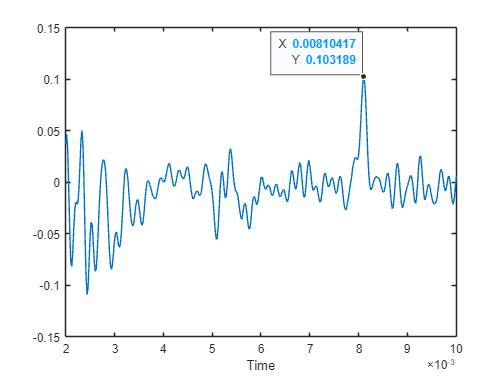

% Riešenie / Solution
middle_sample = vowel_sample(round(length(vowel_sample)/2) - 1024: round(length(vowel_sample)/2) + 1024);
plot(0:1/fs:2048/fs ,cceps(middle_sample))
xlim([0.002, 0.01])
xlabel("Time")

% Generated by matlab after highlighting point
ax = gca;
chart = ax.Children(1);
datatip(chart,0.008104,0.1032);

% Frequency of found peak
1/0.00810417

ans = 123.3933

% Found peak of 0.103, at time 0.00810417
% Frequency of the peak is 123.3933